clear, clc

## DEFINE MODEL

model = 'bestparameters';

% LOAD DATA
MVC = '20';
trial = '2';
% path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Processed Data\Data_old';
% name = 'dataSet1';
path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Processed Data';
name = ['MVC_' MVC '_trial_' trial];
load([path '\' name '.mat'])
clear path, clear name

% LOAD MODEL DATA
[paramsLabel,lb,ub] = load_modeldata(model);
n_neurons = size(spikeTrainsExp,2);

## VISULIZE SPIKE TRAINS

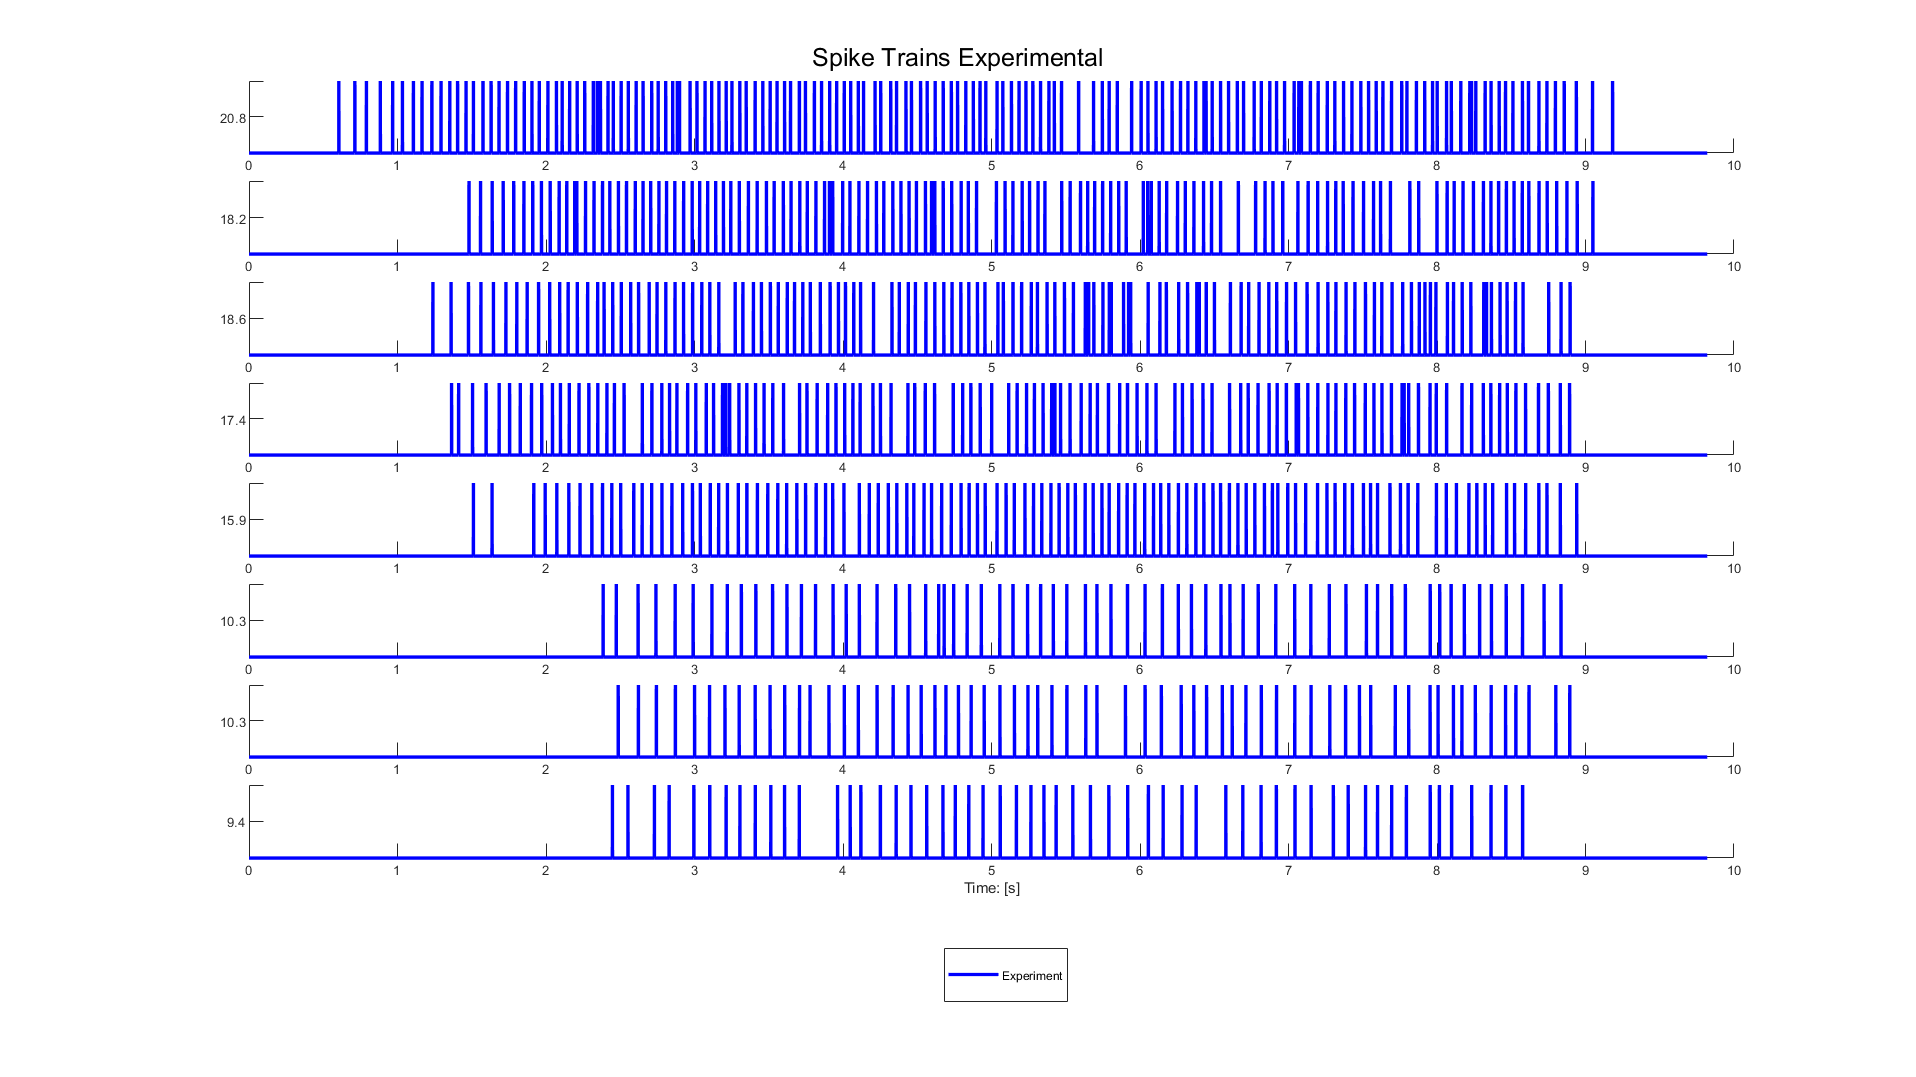

figure, clf
for MNIndex = 1:n_neurons
    spikeTimesExp = find(spikeTrainsExp(:,MNIndex) == 1);
    meanFiringRateExp(MNIndex) = mean(1./diff(spikeTimesExp/2048));
    subplot(n_neurons+1,1,MNIndex), hold on;
    plot(tVec,spikeTrainsExp(:,MNIndex),'b','LineWidth',2)
    yticks(0:0.5:1)
    yticklabels({'',num2str(meanFiringRateExp(MNIndex),'%.1f'),''});
end
hold off
xlabel('Time: [s]')
lg = legend({'Experiment'});
set(gcf,'units','normalized');
set(gcf,'Position',[0, 0, 1, 1]);
set(lg,'Position', [0.5, 0.07, 0.05, 0.05],'units','normalized');
sgtitle('Spike Trains Experimental')

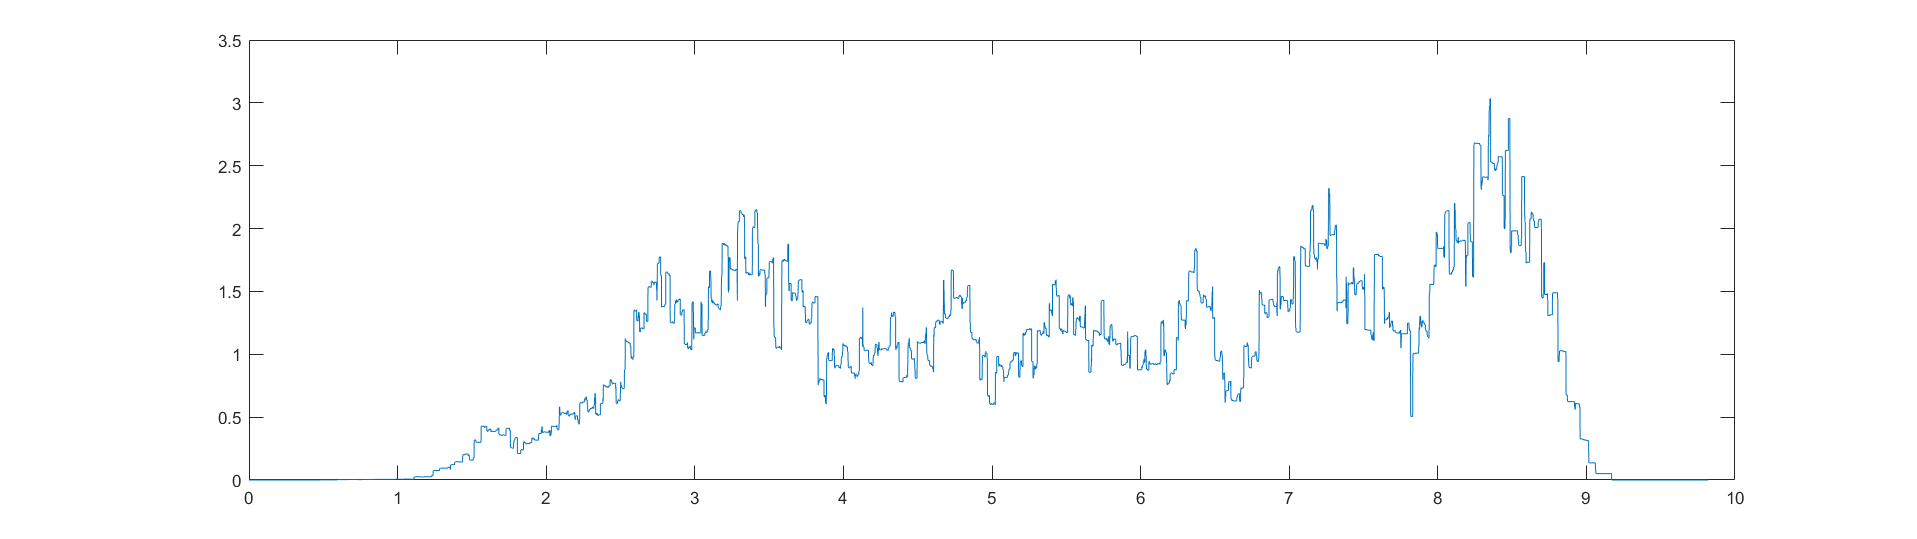

figure, clf
plot(tVec,current)
set(gcf,'units','normalized');
set(gcf,'Position',[0, 0, 1, 0.5]);

## CREATE AN INSTANCE FOR EACH NEURON

% window = 0.25;
for MNIndex = 1:n_neurons
    % Separate the spikes of each neuron
    spikesExp_vec = spikeTrainsExp(:,MNIndex);
    % Creating instance of the class
    Neuron(MNIndex) = NeuronOptimization.Neuron(paramsLabel,lb,ub,current,spikesExp_vec,tVec);
end

## OPTIMIZE THE NEURONS

tic
% Neuron to optimize
ErrFnc = 'moo';
OptAlg = 'godlike';
neuron_num = 1;
MaxGen = 5;    % Stall Generations for all, except multi objective optimization

for MNIndex = neuron_num
    disp('NURON NUMBER:'), disp(MNIndex)
    % Optimize the neuron
    Neuron(MNIndex).optimize(ErrFnc,OptAlg,MaxGen,Neuron(MNIndex).parameters0)
    
    % Plot the neuron
    if contains(OptAlg,'gamultiobj')
        origin = min(Neuron(MNIndex).bestFactor);
        shifted_fitnesses = bsxfun(@minus,Neuron(MNIndex).bestFactor,origin);
        distances_sq = sum(shifted_fitnesses.^2,2);
        [~,idx] = min(distances_sq);
        disp('Best Parameters:'), disp(Neuron(MNIndex).bestParams(idx,:))
        disp('Best Factor:'), disp(Neuron(MNIndex).bestFactor(idx,:))
        disp('Chosen Best Parameters index:'), disp(idx)
        Neuron(MNIndex).plot_spikes(Neuron(MNIndex).bestParams(idx,:))
    else
        disp('Best Parameters:'), disp(Neuron(MNIndex).bestParams)
        disp('Best Factor:'), disp(Neuron(MNIndex).bestFactor)
        Neuron(MNIndex).plot_spikes(Neuron(MNIndex).bestParams)
    end
end
toc

## PLOT MULTIOBJECTIVE OPTIMIZATION (MOO)

Coincidence Factor, Frequency Factor, First Spike Time, Number of Spikes

gKs, dSoma, betaQ, alphaQ

for MNIndex = neuron_num
    disp('Best Factors:'), disp(Neuron(MNIndex).bestFactor)
    figure, clf, hold on
    plot(1:size(Neuron(MNIndex).bestParams,1),Neuron(MNIndex).bestFactor(:,1))
    plot(1:size(Neuron(MNIndex).bestParams,1),Neuron(MNIndex).bestFactor(:,2))
    plot(1:size(Neuron(MNIndex).bestParams,1),Neuron(MNIndex).bestFactor(:,3))
    plot(1:size(Neuron(MNIndex).bestParams,1),Neuron(MNIndex).bestFactor(:,4))
    xlabel('Best Parameter set')
    ylabel('Error value')
    title(['Pareto Front Comparison of Neuron ' num2str(MNIndex)])
    legend({'CoincidenceFactor','frequencyFactor','firstSpikeTime','NumberOfSpikes'},'Location','northeastoutside');
end

## PLOT CHOSEN BEST PARAMETERS (MOO)

minFac = 4;
for MNIndex = neuron_num
    disp('Neuron number:'), disp(MNIndex)
    [~,idx] = min(Neuron(MNIndex).bestFactor(:,minFac));
    disp('Chosen Best Parameters index:'), disp(idx)
    Neuron(MNIndex).plot_spikes(Neuron(MNIndex).bestParams(idx,:))
end

## VISUALIZE ALL PARETO POINTS (MOO)

for MNIndex = neuron_num
    disp('NEURON NUMBER:'), disp(MNIndex)
    for idx = 1:18
        disp('Pareto Number:'), disp(idx)
        disp('Error Factors:'), disp(Neuron(MNIndex).bestFactor(idx,:))
        Neuron(MNIndex).plot_spikes(Neuron(MNIndex).bestParams(idx,:))
    end
end

## PARAMETERSFINAL (SINGLE OPTIMIZATION)

parametersFinal = zeros(n_neurons,length(paramsLabel));
% Save parameters
for MNIndex = 1:n_neurons
    parametersFinal(MNIndex,:) = Neuron(MNIndex).bestParams;
end
for i = 1:length(Neuron)
    Neuron_struct(i) = struct(Neuron(i));
end

## FIND BEST PARAMETERS FROM PARETO FRONT AND PARAMETERSFINAL (MOO)

parametersFinal = zeros(n_neurons,length(paramsLabel));
% Save parameters
for MNIndex = 1:n_neurons
    disp('NEURON NUMBER:'), disp(MNIndex)
    origin = min(Neuron(MNIndex).bestFactor);
    shifted_fitnesses = bsxfun(@minus,Neuron(MNIndex).bestFactor,origin);
    distances_sq = sum(shifted_fitnesses.^2,2);
    [~,idx] = min(distances_sq);
    disp('Chosen Best Parameters index:'), disp(idx)
    parametersFinal(MNIndex,:) = Neuron(MNIndex).bestParams(idx,:);
    %     Neuron(MNIndex).plot_spikes(Neuron(MNIndex).bestParams(idx,:))
end
for i = 1:length(Neuron)
    Neuron_struct(i) = struct(Neuron(i));
end

## SAVE FINAL PARAMETERS 

path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Optimazed Parameters';
% if  window == 0
name = [MVC '_' trial '_' OptAlg '_' ErrFnc '_' model];
% else
%     name = [MVC '_' trial '_' OptAlg '_' ErrFnc '_' model '_w'];
% end
STRUCT.('Neuron') = Neuron_struct;
STRUCT.('parametersFinal') = parametersFinal;
STRUCT.('model') = model;
STRUCT.('OptAlg') = OptAlg;
STRUCT.('ErrFnc') = ErrFnc;
save([path '\' name '.mat'],'-struct','STRUCT')
clear path, clear name, clear STRUCT

## LOAD FINAL PARAMETERS

MVC = '10';
trial = '2';
ErrFnc = 'moo';
OptAlg = 'godlike';
model = 'bestparameters_nothr';
path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Optimazed Parameters';
% path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Optimazed Parameters\Data_old';
name = [MVC '_' trial '_' OptAlg '_' ErrFnc '_' model];
load([path '\' name '.mat'])
clear path, clear name

paramsLabel = Neuron(1).paramsLabel;
lb = Neuron(1).lb;
ub = Neuron(1).ub;
tVec = Neuron(1).tVec;
current = Neuron(1).current;
% Reconstructing spikeTrainsExp
n_neurons = length(Neuron);
spikeTrainsExp = zeros(length(Neuron(1).spikesExp_vec),n_neurons);
for MNIndex = 1:n_neurons
    spikeTrainsExp(:,MNIndex) = Neuron(MNIndex).spikesExp_vec;
end

## FINAL PLOTS

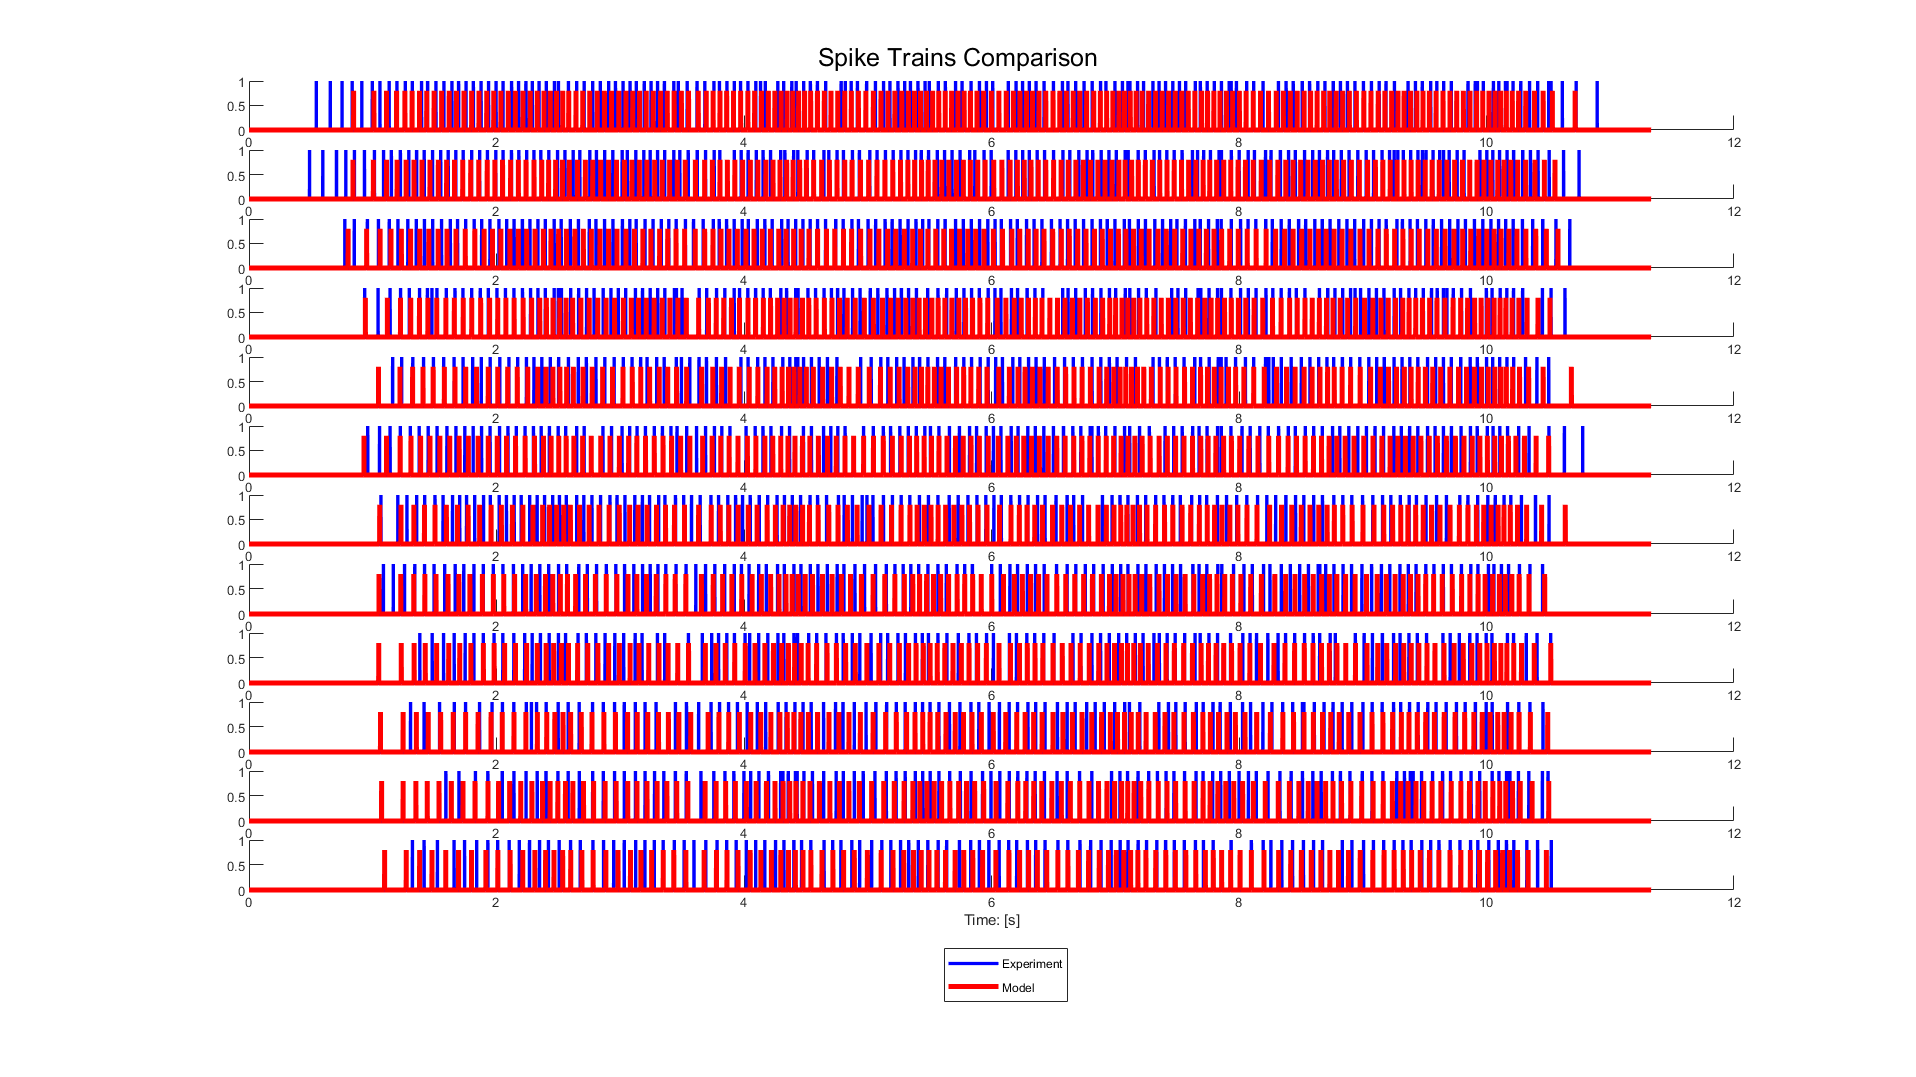

% MakeFinalPlots(paramsLabel,lb,ub,current,spikesExp,parametersFinal,tVec,tspan)
neuronpool_plot = NeuronOptimization.MakeFinalPlots(paramsLabel,lb,ub,current,spikeTrainsExp,tVec,parametersFinal);

% Plot the Spikes
spikeTrainsSim = neuronpool_plot.plot_spikes();

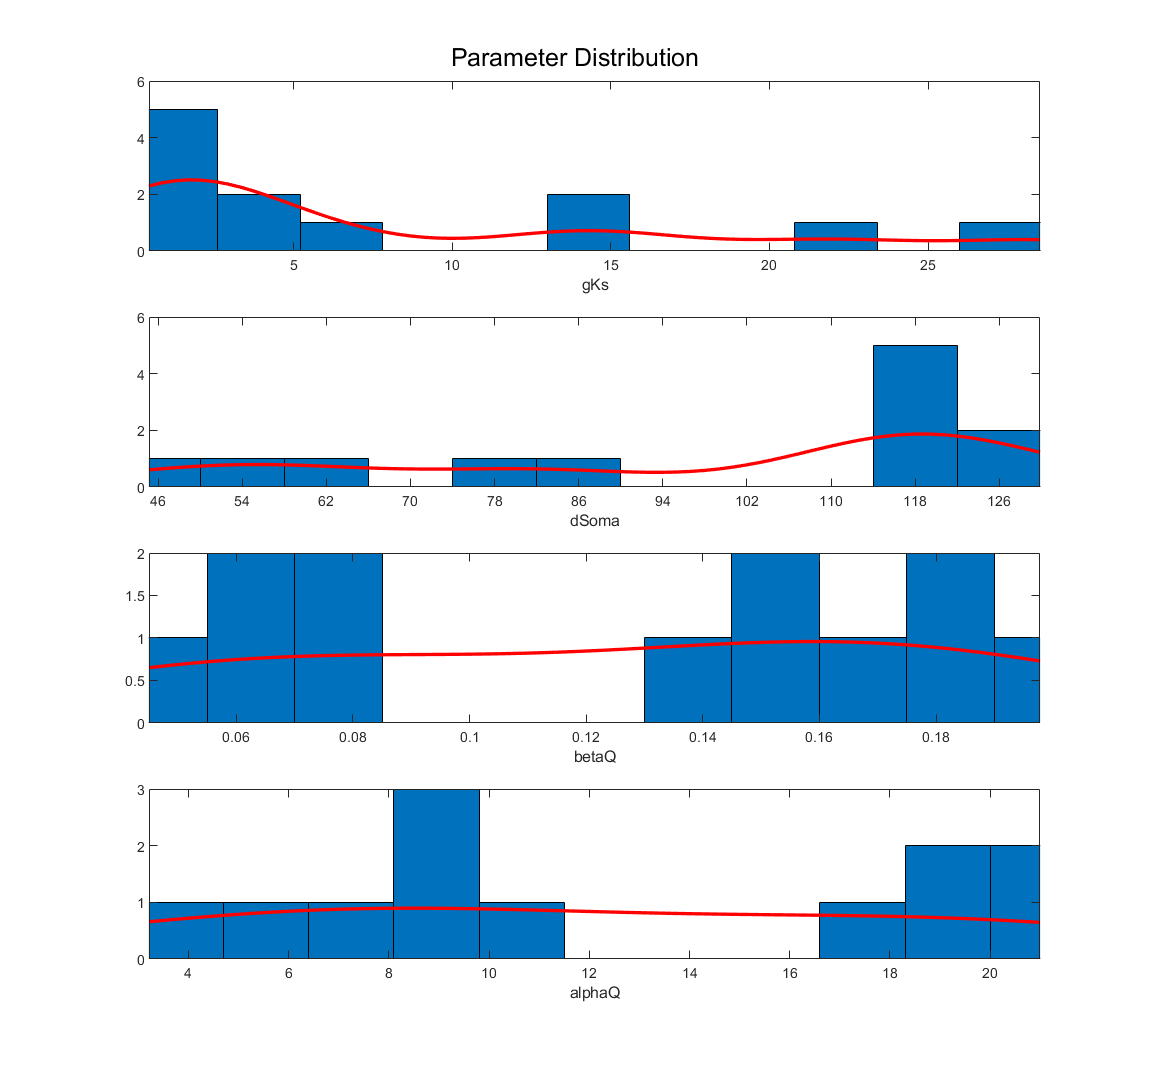

% plot the parameter distribution
neuronpool_plot.plot_histogram();

## TABLE OF FINAL PARAMETERS AND FACTOR

for MNIndex = 1:n_neurons
    neuronBestParams(MNIndex,:) = parametersFinal(MNIndex,:);
    neuronBestFactor(MNIndex,:) = Neuron(MNIndex).bestFactor;
end
VarNames = {'Coincidence Error','Frequency Error','First Spike Time Error','Number of Spikes Error'};
sz = [n_neurons length(paramsLabel)+4];
varTypes = cell(1,sz(2));
varTypes(:) = {'double'};
for i = 1:length(paramsLabel)
    VarNames{4+i} = paramsLabel{i};
end
T = table('Size',sz,'VariableTypes',varTypes,'VariableNames',VarNames);
for i = 1:length(paramsLabel)+4
    if i <= 4
        T(:,i) = num2cell(neuronBestFactor(:,i));
    else
        T(:,i) = num2cell(neuronBestParams(:,i-4));
    end
end
T

T = 12×8 table
    Coincidence Error    Frequency Error    First Spike Time Error    Number of Spikes Error      gKs      dSoma      betaQ      alphaQ
    _________________    _______________    ______________________    ______________________    _______    ______    ________    ______

           1.025             0.011787                1.1085                  0.054217            15.317     58.24    0.068359    18.333
         0.95294             0.060497                1.4337                  0.024691            21.889    56.634     0.06168    4.9908
          1.0167              0.10328              0.069313                  0.046667            13.231     45.13    0.045015    3.2117
         0.90667             0.0

## CHECK TENDENCIES IN THE NEURON PARAMETERS

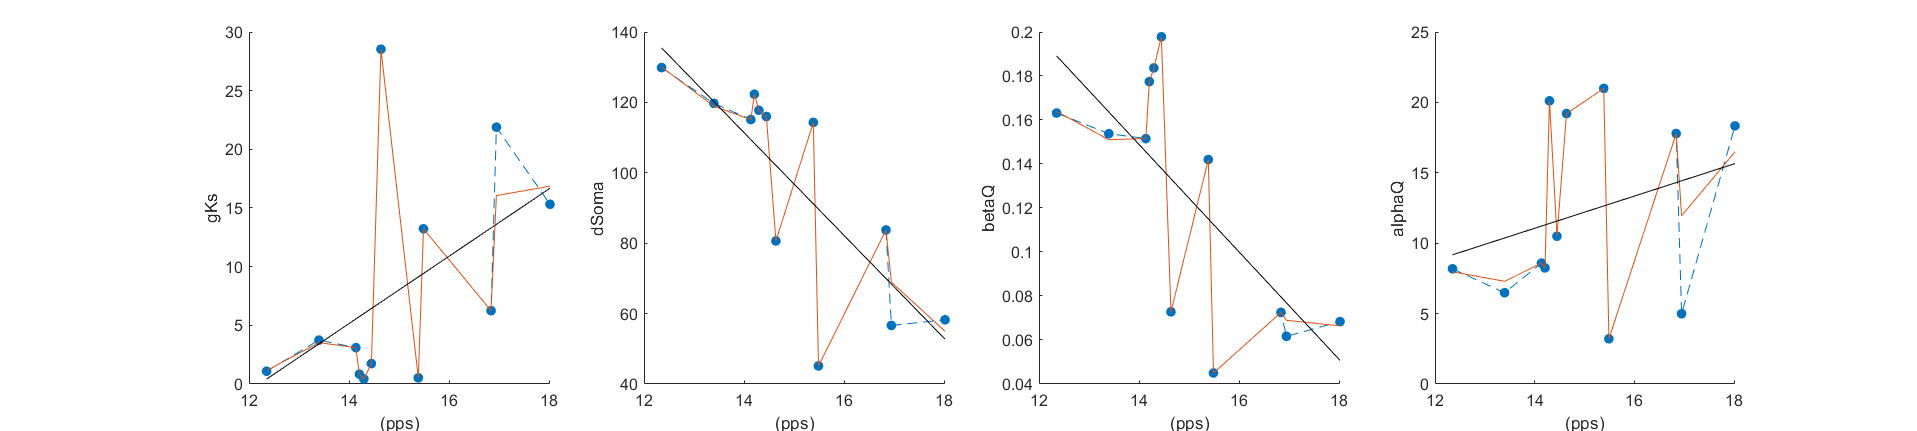

for MNIndex = 1:n_neurons
    spikeTimesExp = find(spikeTrainsExp(:,MNIndex) == 1);
    meanFiringRateExp(MNIndex) = mean(1./diff(spikeTimesExp/2048));
end
[meanFiringRateExp,I] = sort(meanFiringRateExp);
figure, clf
for i = 1:length(paramsLabel)
    subplot(1,length(paramsLabel),i), hold on
    plot(meanFiringRateExp,neuronBestParams(I,i),'.--','MarkerSize',20)
%     smoothedVec = smooth(neuronBestParams(I,i),'loess');
%     plot(meanFiringRateExp,smoothedVec)
    p = polyfit(meanFiringRateExp,neuronBestParams(I,i)',1);
    y = polyval(p,meanFiringRateExp);
    plot(meanFiringRateExp,y,'k')
    xlabel('(pps)')
    ylabel(paramsLabel{i})
end
set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1, 0.4]);

## FUNCTIONS

function [paramsLabel,lb,ub] = load_modeldata(model)
switch model
    case 'normal'
        paramsLabel={'threshold','dSoma','lSoma','resSoma'};
        lb = [11,75,75,600];
        ub = [22,113,113,1200];
        
    case 'single'
        paramsLabel={'threshold','dSoma'};  % When just dSoma is specified lSoma = dSoma
        lb = [10,25];
        ub = [40,85];
        
    case 'conductancebetaQ'
        paramsLabel={'gKf','gKs','betaQ','dSoma'};
        lb = [0.5,8,0.01,70];
        ub = [5,37.5,0.05,113];
        
    case 'justconductances'
        paramsLabel={'gKf','gKs','gNa','dSoma'};
        lb = [0.5,8,10,70];
        ub = [5,37.5,50,113];
        
    case 'all'
        paramsLabel={'threshold','dSoma','lSoma','resSoma','gKf','gKs','gNa'};
        lb = [11,75,75,600,0.5,8,10];
        ub = [22,113,113,1200,5,37.5,50];
        
    case 'ionicchannels'
        paramsLabel={'alphaH','betaH','alphaN','betaN','alphaQ','betaQ'};
        lb = [0.5,4,1.5,0.1,1.5,0.01];
        ub = [22,22,22,22,22,22];
        
    case 'bestparameters'
        paramsLabel={'dSoma','threshold','betaQ'};
        lb = [40,0.2,0.01];
        ub = [113,50,0.2];
        
    case 'bestparameters_nothr'
        paramsLabel={'gKs','dSoma','betaQ','alphaQ'};
        lb = [0.2,40,0.01,1.5];
        ub = [37.5,130,0.2,22];
        
    case 'bestparameters_new'
        paramsLabel={'dSoma','betaQ'};
        lb = [40,0.01];
        ub = [130,0.2];
        
    otherwise
        fprintf('No valid model selected');
end
end